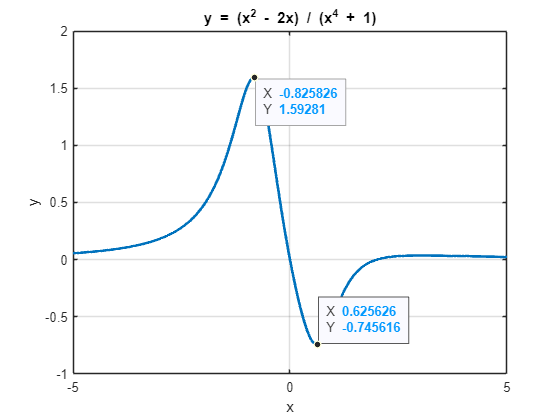

% 1_4_35

% funktionen
fun = @(x) (x.^2 - 2.*x) ./ (x.^4 + 1);

% värdemängd
x_min = -5;
x_max = 5;

% generera X-värden
x_values = linspace(-5, 5, 1000);

% generera Y-värden
y_values = fun(x_values);

% plotta grafen
plot(x_values, y_values, 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('y = (x^2 - 2x) / (x^4 + 1)');
grid on;

% för att visa max och min värde, med x punkterna.
ax = gca;
chart = ax.Children(1);
datatip(chart,-0.83,1.593);
ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,0.63,-0.7456);


% min värde
[min_value, min_x] = fminbnd(fun, x_min, x_max);

% max värde
[max_value, max_x] = fminbnd(@(x) -fun(x), x_min, x_max);

% här är lokala min och max med 3 decimaler för denna funktion:
fprintf('Minimum värde: %.3f för x = %.3f\n', min_value, min_x);

Minimum värde: 0.629 för x = -0.746


fprintf('Maximum värde: %.3f för x = %.3f\n', -max_value, max_x);

Maximum värde: 0.831 för x = -1.593
